Come esplicitato da consegna, tutti i risultati devono essere visualizzati utilizzando:

format long

## 1 . Interpolazione

Si definisce la funzione composta $f\left(x\right)=\sin \left(\cos \left(x\right)\right)+\log \left(2e^x \right)$. 

fun_composta = @(x) sin(cos(x)) + log(2 * exp(x));

Per stabilire un intervallo in cui la funzione è definita e non presenta punti di discontinuità, si può usufruire del comando `ezplot(function)` per osservarne il grafico, in questo modo:

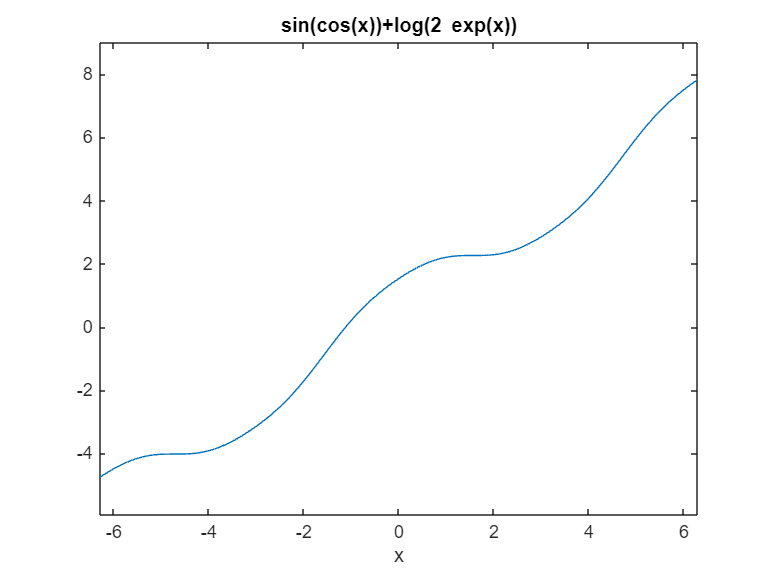

figure(1)
ezplot(fun_composta)

L'intervallo che si è scelto è $\left\lbrack 0,10\right\rbrack$, valori attribuiti, rispettivamente, alle variabili: `a `e  `b`.

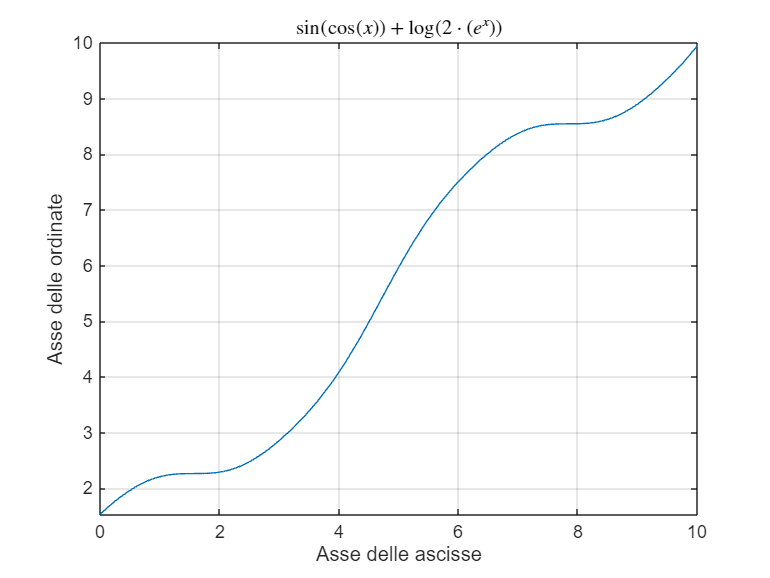

a = 0; %estremo sinistro
b = 10; %estremo destro
figure(2)
fplot(fun_composta, [a, b])
hold on
xlabel('Asse delle ascisse')
ylabel('Asse delle ordinate')
title('$\sin(\cos(x)) + \log(2 \cdot (e^x))$', 'Interpreter', 'LaTex')
hold off
grid on

Come da consegna, definisco $m$ punti $P={\left\lbrace \left(x_i ,y_i \right)\right\rbrace }_{i=1}^8$ con $m\in N$ ed, in questo caso, uguale a 8.

m = 8;
x = linspace(a, b, m);
x = x';
y = fun_composta(x); % Ordinate ottenute dal valore della funzione nelle ascisse 

Il **fitting dei dati** è la ricostruzione di un **fenomeno continuo **a partire da un suo campionamento discreto. In input si hanno:

- **m** dati (caso 1D: $x_i$, $y_i$);

- un **insieme **$F$ di funzioni (**modello**).

In output abbiamo:

- una **funzione **$f$ dell'insieme di funzioni **F** (il **descrittore continuo** dei dati).

Esistono due tipi di ricostruzione:

- **esatta**: viene chiamata "***interpolazione***" con dati senza errore o con errore trascurabile;

- **approssimata**: viene detta "***approssimazione***" utilizzando dati affetti da errore. È una ricostruzione di **trend**.

### PUNTO 1.1

Definire un insieme $\mathcal{F}$di funzioni modello polinomiali. Scegliere un'opportuna base così da determinare il polinomio $p$  $\in$ $\mathcal{F}$ che interpola $f$ nei nodi $x_i$. Costruire il relativo sistema lineare $Ba=y$ e risolverlo (non usare il comando backslash di MATLAB).  Calcolare inoltre l'indice di condizionamento della matrice $B$.

bb = @(x, i) x.^(i-1); 
B = zeros(m, m);
for i = 1:m
    B(:, i) = bb(x, i); % Matrice di Van Der Monde
end

Verifichiamo, attraverso il calcolo del rango della matrice (con il comando `rank(matrix)`) e del determinante ( `det(matrix) `) , se la matrice è non-singolare o meno:

rank(B) %rango della matrice

ans =      8


det(B) %determinante della matrice

ans =      2.726413015085269e+15


È non-singolare: il **determinante** e il **rango **sono diversi da 0.

coeffs = SGauss(B, y); %calcolo dei coefficienti per il polinomio interpolante
cond(B) %indice di condizionamento della matrice 

ans =      2.982295695668935e+08


L'**indice di condizionamento** (calcolato con la parola chiave `cond()` che ha come parametro in input la matrice `B` dei coefficienti) è un valore abbastanza alto (ordine di ${10}^8$) perchè rappresenta la matrice quadrata  $m\times m$ (8 x 8, con lo stesso numero di coefficienti e di incognite) per la risoluzione del sistema ($\textrm{Ba}=y$). 

Con questi passaggi, è stata presentata l'**interpolazione di Lagrange**, con la seguente condizione di interpolazione:

*"Trovare, se esiste, *$f$* in *$F$* tale che:*

$f\left(x_i \right)=y_i \;\;\textrm{con}\;i=1:m$*"*

### PUNTO 1.2

Si valuta il polinomio $p$ su una griglia $N=333$:

xx = a + (b - a) * rand(333, 1);
xx = sort(xx);

Con queste righe di codice, si genera una griglia di n punti di valutazione distribuiti casualmente nell'intervallo considerato. 

BB = zeros(length(xx), m);
for i = 1:m
    BB(:, i) = bb(xx, i);
end

Qui di seguito, sono riportati i valori del polinomio interpolante:

val_pol = BB * coeffs;

L'errore di interpolazione si calcola considerando i valori calcolati nella riga di codice precedente e i valori della funzione nei punti della griglia.

errore_inter = abs(val_pol - fun_composta(xx))

errore_inter =    0.019793561079363
   0.045334625092624
   0.055546535717594
   0.055775512503839
   0.084228479411442
   0.085116516663462
   0.087180165797865
   0.089086947459514
   0.092619222018479
   0.094179812107791


L'errore è abbastanza trascurabile ed è quasi vicino allo zero.

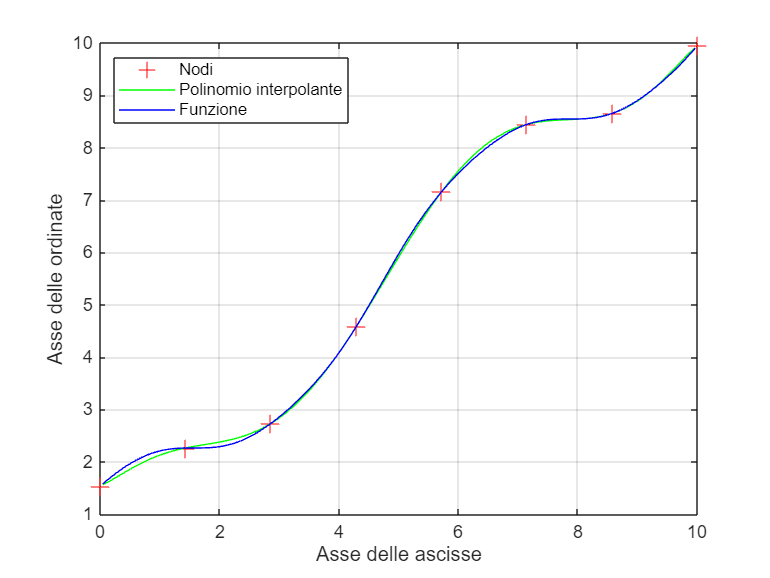

figure(3)
plot(x, y, '+r', 'MarkerSize', 10) %nodi
hold on
plot(xx, val_pol, 'g', xx, fun_composta(xx), 'b') %visualizzazione del polinomio interpolante e della funzione originale
xlabel('Asse delle ascisse')
ylabel('Asse delle ordinate')
legend('Nodi', 'Polinomio interpolante', 'Funzione', 'Location', 'northwest')
hold off
grid on

### PUNTO 1.3

Si interpolano i punti $P$ mediante una spline $s$ di terzo grado di tipo not-a-knot. Si valuta l'interpolante ottenuto sulla griglia di $N$ punti di valutazione nel punto 1.2.

#### Funzione spline di primo grado

Un **polinomio a tratti interpolante** è una **funzione continua** in $\left\lbrack a,b\right\rbrack$, con derivata prima (eventualmente) discontinua (**la discontinuità può essere solo nei breakpoint**). 

NB:

- il **grado** della spline interpolante non dipende dal numero di nodi;

- se la spline lineare avesse derivata prima continua, allora la spline lineare sarebbe un polinomio di grado 1.

#### Funzione spline cubica (spline di terzo grado) 

- è un **polinomio a tratti di terzo grado**;

- è una** funzione continua** in [a, b];

- è una funzione con **derivata prima continua** in $\left\lbrack a,b\right\rbrack$;

- è una funzione con** derivata seconda continua** in $\left\lbrack a,b\right\rbrack$;

- la **derivata terza è (eventualmente)** **discontinua** (la discontinuità può essere solo nei breakpoint).

- l'insieme delle spline cubiche contiene strettamente l'insieme dei polinomi i grado 3;

- una spline cubica con derivata terza continua è un** polinomio di grado 3**.

#### **Spline naturale e spline not-a-knot (offerta da Matlab)**

 Entrambe impongono le seguenti condizioni di:

- **interpolazione**: impostata sui nodi esterni e interni;

- **continuità della derivata prima **nel nodo di interpolazione per i nodi interni;

- **continuità della derivata seconda** nel nodo di interpolazione per i nodi interni.

    Altre due condizioni:

- **Spline naturale**: derivata seconda agli estremi;

- **Spline not-a-knot**: derivata terza continua nel secondo e nel penultimo breakpoint.

sp = spline(x, y); %creazione spline con il comando di Matlab

'`ppval`' è un comando che viene utilizzato in Matlab per valutare i polinomi a tratti (splines) in punti precisi. Ha in input: la spline (`sp`) e la griglia di punti `xx`.

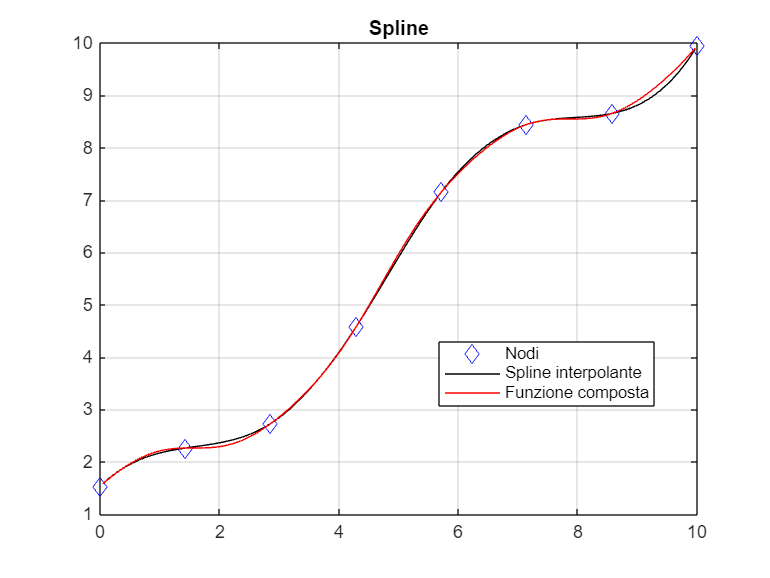

y_sp = ppval(sp, xx);
figure(4)
plot(x, y, 'db', 'MarkerSize', 7)
hold on
plot(xx, y_sp, 'k')
plot(xx, fun_composta(xx), 'r')
title('Spline')
legend('Nodi', 'Spline interpolante', 'Funzione composta', 'Location', 'best')
hold off
grid on

### PUNTO 1.4

Si definisce un nuovo insieme di punti $Q = \{(x_j, y_j)\}_{j=1}^n$ le cui ascisse sono i nodi di Chebyshev in $[a,b]$ e le cui ordinate sono i valori corrispondenti assunti da $f(x)$. Costruire, poi, il polinomio interpolante i punti $Q$ e valutarlo sulla griglia di valutazione generata al punto 1.2.

#### Generazione di una griglia di nodi di Chebychev

Si divide l'angolo $\pi$ in $n-1$ angoli uguali. I punti della semicircoferenza unitaria sono equispaziati. Le ascisse di tali punti sono i** nodi di Chebychev**. 


$$x_k^{\textrm{Cheb}} =\cos \left(\frac{k\pi }{n-1}\right),k=0:n-1$$


I nodi di Chebychev sono più densi agli estremi dell'intervallo. 

n = 14; %numero di nodi 
xcheb = cos((0 : n-1)*pi/(n-1)); %si utilizza la formula precedentemente scritta per il calcolo delle ascisse

I nodi di Chebychev per un intervallo $\left\lbrack a,b\right\rbrack$ si calcolano in questo modo:


$$x_k^{\textrm{Cheb}\left\lbrack a,b\right\rbrack } =\frac{a+b}{2}+\frac{b-a}{2}x_k^{\textrm{Cheb}} ,\;k=0:n-1$$


xx_cheb = ((a+b)/2 + (b-a)/2 * xcheb)'; %si utilizza questa formula perchè abbiamo un intervallo [a, b]
ycheb = fun_composta(xx_cheb); % si calcola la funzione nelle ascisse generate

Si crea una matrice, considerando quella di Van Der Monde, utilizzando la funzione anonima `bb` espressa precedentemente:

Bchb = zeros(n,n);
for j = 1:n
    Bchb(:, j) = bb(xx_cheb, j);
end

Si calcolano i coefficienti (`coefs_cheb`) con la risoluzione del sistema $\textrm{Ba}=y$ :

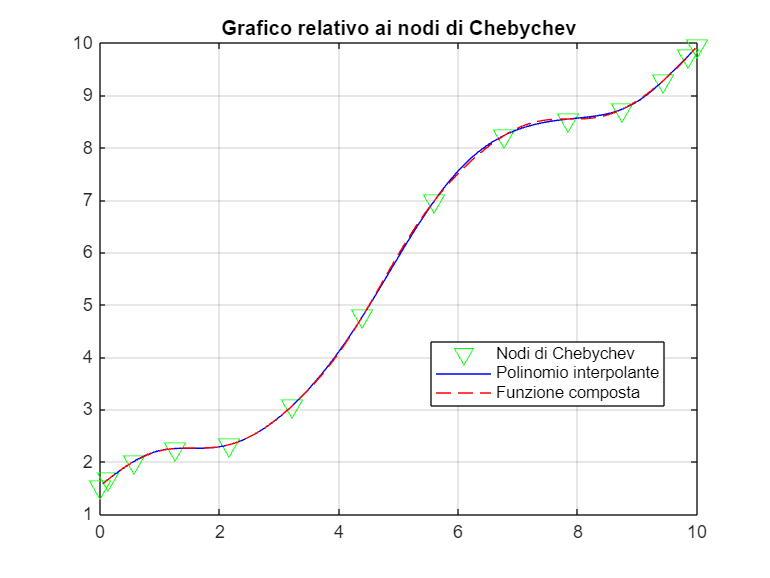

coefs_cheb = SGauss(Bchb, ycheb);
%Si ripetono i processi precedenti considerando una griglia di 333 punti
BB_chb = zeros(333, n);
for j = 1 : n
    BB_chb(:, j) = bb(xx, j);
end
yy_cheb = BB_chb * coefs_cheb;
figure(5)
plot(xx_cheb, ycheb, 'gv', 'MarkerSize', 10) %nodi di Chebychev
hold on
plot(xx, yy_cheb, 'b')
plot(xx, fun_composta(xx), '--r')
title('Grafico relativo ai nodi di Chebychev')
legend('Nodi di Chebychev', 'Polinomio interpolante', 'Funzione composta', 'Location', 'best')
hold off
grid on

### PUNTO 1.5

Si calcola, adesso, l'errore di Chebychev (`erroreCheb`) e si mostra graficamente l'andamento dell'errore di interpolazione. 

erroreCheb = abs(fun_composta(xx) - yy_cheb)

erroreCheb =    0.001969659561441
   0.000949479551023
   0.000342275966095
   0.000375416888602
   0.004761616906469
   0.004861244880180
   0.005066184184835
   0.005216683808018
   0.005368972928795
   0.005370254908734


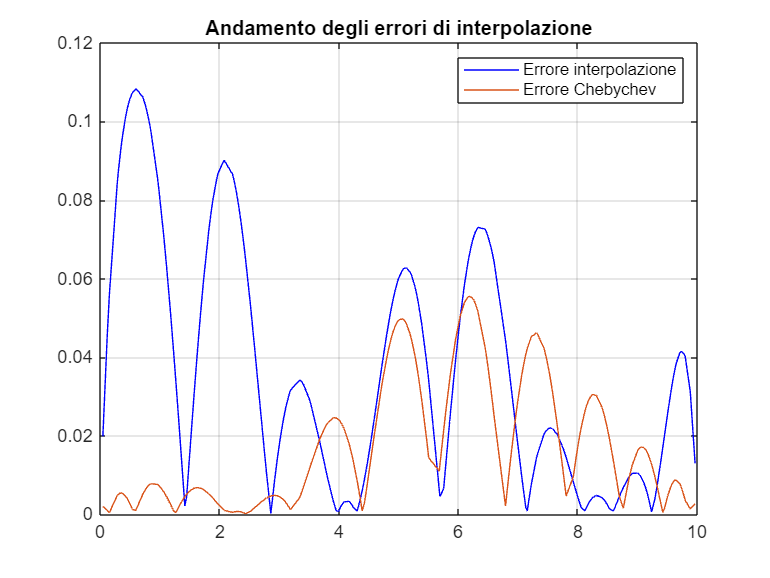

figure(6)
plot(xx, errore_inter, '-b', 'MarkerSize', 8)
hold on
plot(xx, erroreCheb, 'MarkerSize', 8)
title('Andamento degli errori di interpolazione')
legend('Errore interpolazione', 'Errore Chebychev')
hold off
grid on

Infine lo si confronta con quello precedentemente calcolato al punto 1.2 (`errore_inter`).

erroreCheb < errore_inter

ans = 333×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


L'errore di Chebychev (`erroreCheb`) risulta essere minore rispetto all'errore di interpolazione (`errore_inter`).

## 2. Interpolazione con curve parametriche

La consegna in questione proponeva tre curve. Considerando la terza, si avrà: $\begin{cases}
x = a \cdot \theta \cdot \cos(\theta) \\
y = a \cdot \theta \cdot \sin(\theta)
\end{cases}
\quad 0 \leq \theta \leq 4\pi$

Ogni punto della curva (individuato da un'ascissa e da un'ordinata) è considerato come una funzione di un parametro. L'ascissa e l'ordinata, di conseguenza, sono anch'esse funzioni di parametro ($P\left(t\right)=\left(x\left(t\right),y\left(t\right)\right)$). Al variare del paramtero, si ottengono tutti i punti della curva.

La variabile '`cf`' è la $a$ della consegna. 

x_curva = @(theta, cf) cf .* theta .* cos(theta); %ascissa
y_curva = @(theta, cf) cf .* theta .* sin(theta); %ordinata

Si campiona la curva scelta in $n$ punti $P={\left\lbrace \left(x_i ,y_i \right)\right\rbrace }_{i=1}^n$ corrispondenti a $n=25$ punti $t_i$ equispaziati nell'intervallo $\left\lbrack 0,10\right\rbrack$ in cui varia il parametro $t$.  

cf = linspace(0, 10, 25); %generiamo una griglia di punti
theta = linspace(0, 4*pi, 25); %generiamo una griglia di intervalli

### PUNTO 2.1

Si costruiscono due spline parametriche $p_x$ e $p_y$ che interpolino rispettivamente i punti $\left(t_i ,x_i \right)$  e i punti $\left(t_i ,y_i \right)$ con $i=1,\ldotp \ldotp ,n$

spl_x = x_curva(theta, cf); %spline relativa alle ascisse
spl_y = y_curva(theta, cf); %spline relativa alle ordinate

### PUNTO 2.2

Si valutano le spline parametriche su una griglia fitta $\Gamma$ opportuna e viene mostrato il grafico della curva parametrica interpolata.

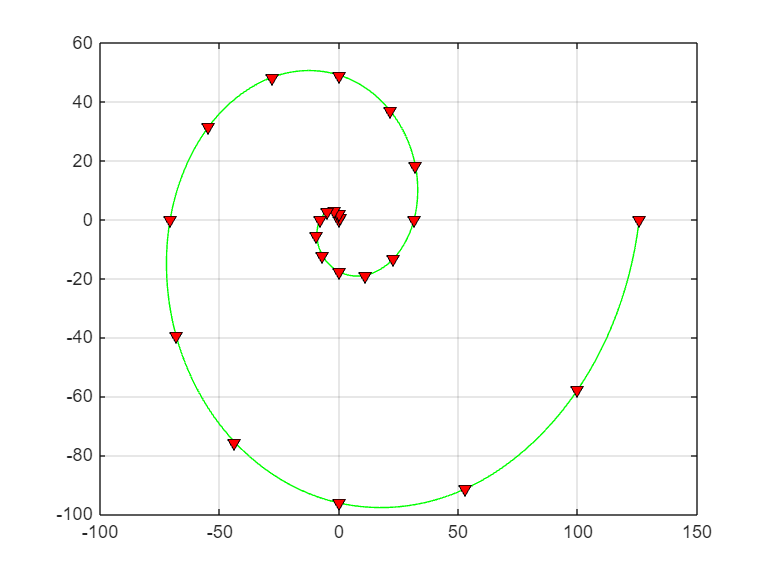

xx_curve = linspace(0, 10, 333); %generare una griglia di 333 punti
x_spl = spline(cf, spl_x, xx_curve); %spline relativa alle ascisse costruita considerando la griglia generata dal linspace precedente
y_spl = spline(cf, spl_y, xx_curve); %spline relativa alle ordinate costruita considerando la griglia generata dal linspace precedente
figure(7)
plot(x_spl, y_spl, '-g')
hold on
plot(spl_x, spl_y, 'kv', 'MarkerFaceColor', 'r')
hold off
grid on

### PUNTO 2.3

Ripetere i punti 2.1 e 2.2 su un insieme di $m=50$ punti $S = \{(x_j,y_j)\}_{j=1}^m$ le cui ascisse ed ordinate sono valori ottenuti dall'utilizzo del comando `ginput` usato su una immagine a propria scelta oppurtunamente caricata (usare `imread). `Le coordinate devono essere estese aggiungendo in coda un punto fittizio coincidente col primo punto, in modo tale che `x` e `y` siano i vettori delle coordinate dei vertici di un poligono (chiuso). 

Ho scelto come immagine '`spoon.png' `che raffigura un cucchiaio.

figure(8)

Per leggere l'immagine che ho scelto e importarla nell'ambiente di lavoro di Matlab come matrice, ho utilizzato la funzione

'`spoon = imread('spoon.png')`'. Quest'ultima supporta una varietà di formati di immagini comuni, come JPEG, PNG (come nel caso qui presentato) ecc... 

La funzione utilizzata ha come variabili:

- in input:` filename `('`spoon.png`') , una stringa che specifica il nome del file dell'immagine da leggere. Può includere il percorso completo del file;

- in output: la matrice dell'immagine risultante (in questo caso '`spoon`' ).

spoon = imread('spoon.png');
%imshow(spoon)
%[spoonx, spoony] = ginput(50);
%save('DatiHW2.mat', 'spoonx', 'spoony');

I processi che sono esplicitati in queste tre righe di codice commentate sono:

- `imshow(spoon)` visualizza un'immagine memorizzata nella variabile spoon`;`

- `[spoonx, spoony] = ginput(50);` richiede all'utente di selezionare dei punti (imponendo un limite di 50) sull'immagine visualizzata. Restituirà la variabile `spoonx` per le coordinate $x$ e la variabile `spoony` per la variabile $y$.

- `save('DatiHW2.mat', 'spoonx', 'spoony')` salva i dati, relativi alle coordinate dei punti presi sull'immagine, in un file binario (file `.mat`) chiamato '`DatiHW2`'.

Le righe sono commentate perchè ad ogni esecuzione, in caso contrario, si richiederebbe all'utente di tracciare dei punti sull'immagine. Ora, avendoli già tracciati e immagazzinati nel file, non c'è bisogno di ripetere il processo di tracciamento dei punti. 

load('DatiPROJECT2.mat');

'`load('DatiHW2.mat`'`)`' carica le variabili salvate nel file `.mat` nel workspace di Matlab, in modo tale da poter essere utilizzate.

spoonx(1) = spoonx(end);
spoony(1) = spoony(end);

Le prime coordinate vengono impostate uguale alle ultime per avere un percorso chiuso di punti. (come richiede la consegna)

image(spoon) %si visualizza l'immagine
hold on
plot(spoonx, spoony, '--b', 'LineWidth', 1.5) 

Traccia una linea blu tratteggiata intorno all'immagine, creando una sagoma. 

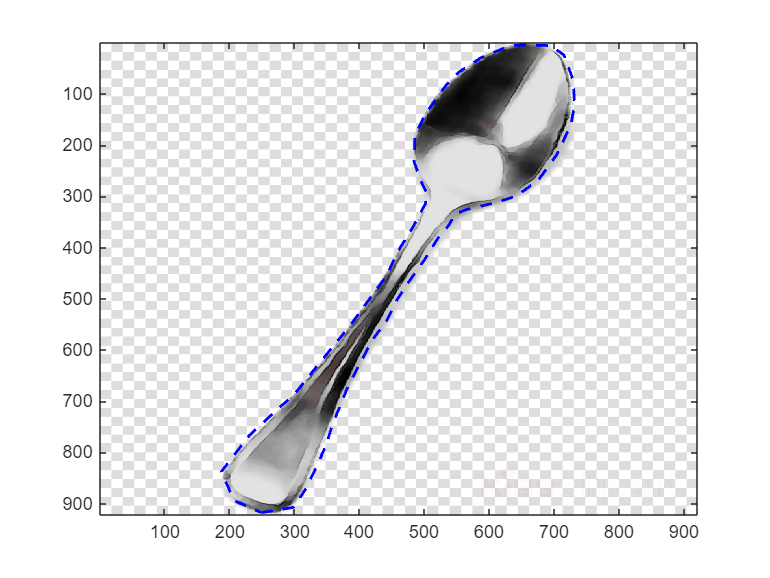

hold off

spoon_t = 1:length(spoonx);
ttspoon = linspace(spoon_t(1), spoon_t(end), 333); %genera un vettore con 333 punti equispaziati
spoonx_cen = mean(spoonx); 
spoony_cen = mean(spoony);

Calcola le medie di `spoonx` e `spoony`. 

spoonx = spoonx - spoonx_cen;
sponny = spoony - spoony_cen;

Questi passaggi centrano i dati dei punti sottraendo le loro medie, in modo che il centro dei punti sia all'origine $\left(0,0\right)$.

spoonx_sp = spline(spoon_t, spoonx, ttspoon); %spline relativa alle ascisse
spoony_sp = spline(spoon_t, spoony, ttspoon); %spline relativa alle ordinate
figure(9)
plot(spoonx, spoony, '+g', spoonx_sp, spoony_sp, '--r') %rappresentazione spline
hold on
title('Ricostruzione con spline')
xlabel('Asse delle ascisse')
ylabel('Asse delle ordinate')
set(gca, 'YDir', 'reverse')

'`set(gca, 'YDir', 'reverse')`' : inverte l'asse delle y, poichè le coordinate delle immagini hanno spesso l'origine in alto a sinistra.

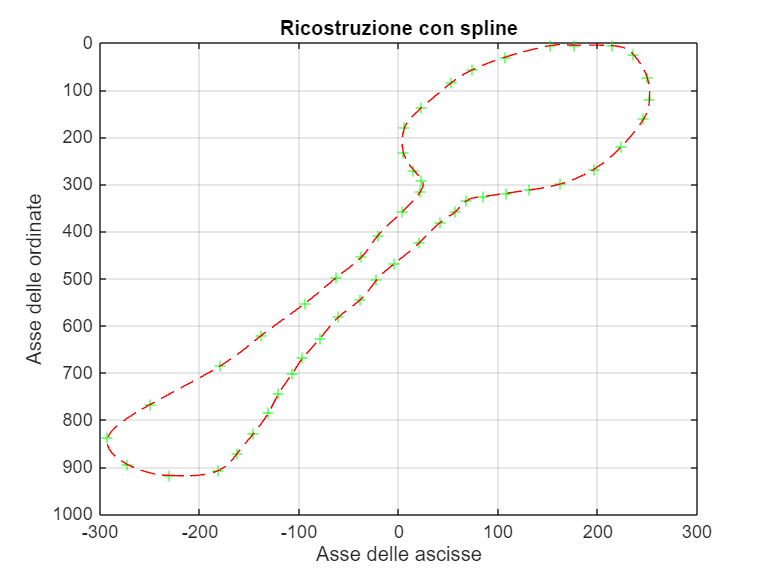

hold off
grid on %griglia attiva

La ricostruzione è andata buon fine.

### PUNTO 2.4

Ricostruire inoltre la curva parametrica passante per i punti definiti al punto 2.3 mediante le cubiche di Hermite (non spline cubiche). Calcolare la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite su $\Gamma$.

#### Cubica di Hermite

- è un **polinomio a tratti di terzo grado**;

- è una **funzione continua in **$\left\lbrack a,b\right\rbrack$;

- è una funzione che ha **derivata prima** **continua **in $\left\lbrack a,b\right\rbrack$;

- la **derivata seconda** è (eventualmente) **discontinua **(la discontinuità può essere solo nei breakpoint);

- l'insieme delle cubiche di Hermite a tratti contiene strettamente l'**insieme delle spline cubiche**;

- una cubica di Hermite con **derivata seconda continua** è una **spline cubica**.

#### Interpolazione con cubiche di Hermite a tratti (shape preserving)

Dati $n$ punti da interpolare, si vuole costruire una cubica di Hermite a tratti che** non oscilli tra nessuna coppia di nodi consecutivi**. Questo può essere risolto con la determinazione automatica dei valori delle pendenze in modo che la funzione interpolante non oscilli intorno a ogni nodo. Ci sono, quindi, due situazioni che possono verificarsi:

- **Pendenza di sinistra e pendenza di destra con segno opposto** (o **una delle due è nulla**): **imporre la pendenza nel nodo nulla** (**nodo di massimo** o **di minimo locale discreto**).

- **Pendenza di sinistra e pendenza di destra con segno uguale**: **imporre la pendenza nel nodo uguale alla media armonica delle pendenze**:


$$\frac{1}{d_k^{\textrm{nodo}} }=\frac{1}{2}\;\left(\frac{1}{d_k^{\sin } }+\frac{1}{d_k^{\textrm{des}} }\right)$$


' `cubica_HermX = pchip(spoon_t, spoonx, ttspoon);`

`cubica_HermY = pchip(spoon_t, spoony, ttspoon);` '

`pchip` viene utilizzato per creare una cubica di Hermite con shape preserving.

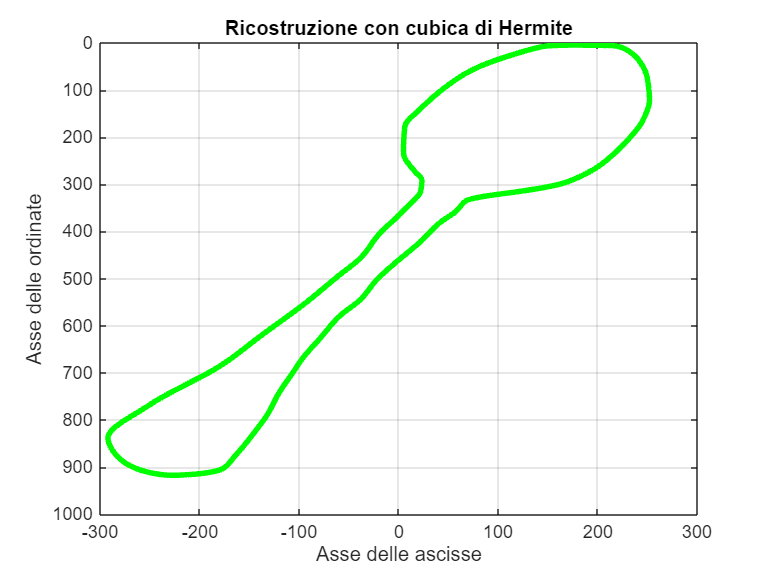

cubica_HermX = pchip(spoon_t, spoonx, ttspoon);
cubica_HermY = pchip(spoon_t, spoony, ttspoon);
figure(10)
plot(cubica_HermX, cubica_HermY, 'g', 'LineWidth', 3)
hold on
title('Ricostruzione con cubica di Hermite')
xlabel('Asse delle ascisse')
ylabel('Asse delle ordinate')
set(gca, 'YDir', 'reverse') %per invertire l'asse y
hold off 
grid on

Anche la ricostruzione con la cubica di Hermite risulta essere andata a buon fine.

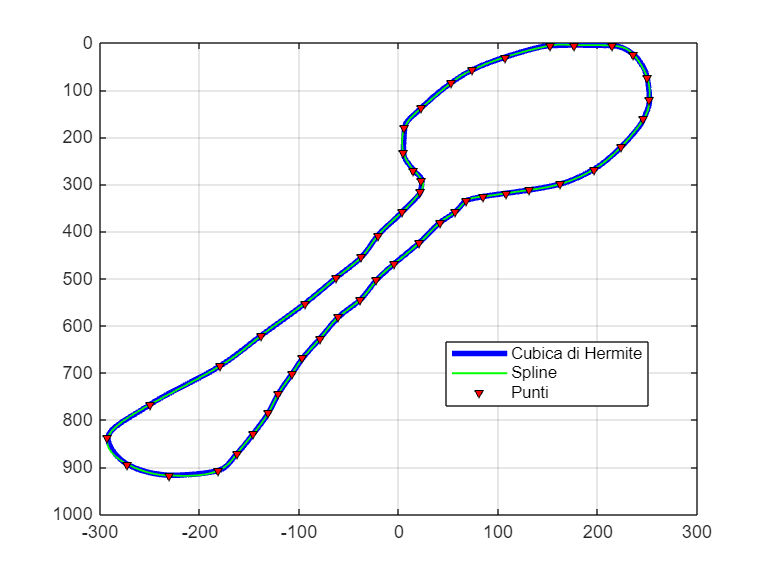

figure(11)
plot(cubica_HermX, cubica_HermY, 'b', 'LineWidth', 3) %visualizza la cubica con una linea blu
hold on
plot(spoonx_sp, spoony_sp, 'g', 'LineWidth', 1) %visualizza la spline con una linea verde
plot(spoonx, spoony, 'kv', 'MarkerFaceColor', 'r', 'MarkerSize', 4) %rappresenta i nodi considerati
set(gca, 'YDir', 'reverse') %inverte l'asse y
legend('Cubica di Hermite', 'Spline', 'Punti', 'Location', 'best')
hold off
grid on

Questo grafico confronta la ricostruzione con spline e cubica.

Si calcola la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite su $\Gamma$ con la funzione '`norm`' . 

normaInf = norm(cubica_HermY, inf)

normaInf =      9.175996216897855e+02


## 3. Approssimazione

L'**approssimazione dei dati** ha lo scopo di trovare (se esiste) $f$ in $F$ tale che:


$$\left|f\left(x_i \right)-y_i \right|\;\;è\;\textrm{piccolo},i=1:m$$


Il tutto considerando:

- $m\;\textrm{punti}\;p_i$ (di coordinate: $x_i ,y_i$);

- l'insieme $F$ (detto modello).

Lo **scostamento di una funzione** da un insieme di punti è misurato dalla **grandezza del vettore degli scostamenti elementari **(**norma del vettore degli scostamenti elementari**). Il problema dell'approssimazione dei dati dipende dalla scelta della norma. Le scelte più comuni sono:

- **NORMA 2: **${\left\|r\right\|}_2 =\sqrt{{r_1 }^2 +{r^2 }_2 +\ldotp \ldotp \ldotp +{r^2 }_m \;}=\sqrt{r^T r}$;

- **NORMA 1**: ${\left\|r\right\|}_1 =\left|r_1 \right|+\left|r_2 \right|+\ldotp \ldotp \ldotp +\left|r_m \right|\;;$

- **NORMA **$\infty$ : ${\left\|r\right\|}_{\infty } =\;\max \left(\left|r_1 \right|,\left|r_2 \right|,\ldotp \ldotp \ldotp ,\left|r_m \right|\right)$.

Fissato il tipo di norma, diremo che lo scopo dell'approssimazione è: **trovare (se esiste) la **$f$** in **$F$** che ha scostamento minimo dai dati**. Il metodo più conosciuto è chiamato "**Minimi Quadrati (Least Squares)**" e si basa su questa condizione: 


$${\left\|r\right\|}_2 \;\;è\;\;\textrm{minima}$$


Si generano un insieme di $n=16$ punti $C=\{(t_i,y_i)\}_{i=1}^n$ le cui ascisse $t_1 ,t_2 ,\ldotp \ldotp \ldotp ,t_n$ appartengono all'intervallo $\left\lbrack 3,4\right\rbrack$ e i valori $y_i$ sono i valori pertubati della funzione $f\left(t\right)=t^3 -2t+17$ nei punti $t_i$, dove la perturbazione si intende introdotta aggiungendo un errore casuale tra 0 e 1 ad ogni valore $y_i$.

napprox = 16; % n = 16 punti da generare
x1 = 3; %estremo sinistro
x2 = 4; %estremo destro

Con il comando `linspace` che ha come parametri gli estremi dell'intervallo e la quantità dei punti da considerare, si generano i punti richiesti dalla consegna.

t = linspace(x1, x2, napprox);
fun_approx = @(t) t.^3 - 2.*t + 17; %definizione della funzione della consegna
y_approx = fun_approx(t); %i valori della funzione negli n punti generati

Calcoliamo la pertubazione addizionando i valori della funzione nei punti generati e i valori (tra 0 e 1) generati casualmente con il comando `rand`.

y_pertubato = y_approx + rand(1, napprox)

y_pertubato =   38.984063724379155  39.874131372877628  41.601920048632365  43.740409740055547  45.523748032172605  47.860058008386389  49.843493413390753  52.679926761074022  54.965369076873600  56.508676997680794  59.700821058479953  61.836823130102253  64.694835615008799  67.625500530844477  70.929107354647314  73.417744104316668


Il vettore contenente i 16 punti viene trasposto così da costruire la matrice `Bmat`.

t = t';

### PUNTO 3.1

Costruire e valutare su una griglia di 73 punti la cubica dei minimi quadrati approssimante i dati.

Bmat = [t.^3 t.^2 t ones(size(t))] %matrice per la cubica dei minimi quadrati

Bmat =   27.000000000000000   9.000000000000000   3.000000000000000   1.000000000000000
  28.840296296296302   9.404444444444445   3.066666666666667   1.000000000000000
  30.762370370370370   9.817777777777778   3.133333333333333   1.000000000000000
  32.768000000000008  10.240000000000002   3.200000000000000   1.000000000000000
  34.858962962962963  10.671111111111111   3.266666666666667   1.000000000000000
  37.037037037037038  11.111111111111112   3.333333333333333   1.000000000000000
  39.303999999999995  11.559999999999999   3.400000000000000   1.000000000000000
  41.661629629629630  12.017777777777779   3.466666666666667   1.000000000000000
  44.111703703703697  12.484444444444444   3.533333333333333   1.000000000000000
  46.656000000000006  12.960000000000001   3.600000000000000   1.000000000000000


    $r$ (il vettore dei residui) dipende dagli n coefficienti $a_1 ,a_2 ,\ldotp \ldotp \ldotp ,a_n \;$ (considerando il modello lineare costituito da funzioni che sono univocamente determinate da $n$ coefficienti). 

La norma del vettore dei residui, a questo proposito, risulterà essere una funzione degli $n$ coefficienti. Minimizzare ${\left\|r\right\|}_2$ ci permette di considerare anche ${\left\|r\right\|}_2^2$. 


$$\min_{a_1 ,a_2 ,\ldotp \ldotp \ldotp ,a_n } \;{\left\|r\right\|}_2^2$$


Le incognite del problema sono gli n valori dei coefficienti $a_1 ,a_2 ,\ldotp \ldotp \ldotp ,a_n$ che minimizzano la funzione ${\left\|r\right\|}_2^2 =g\left(a_1 ,a_2 ,\ldotp \ldotp \ldotp ,a_n \right)$.

Essendo questa funzione derivabile, possiamo utilizzare due approcci:

- di** analisi matematica**: si considera un punto in cui si annullano le $n$ derivate parziali prime della funzione (ovvero, punto in cui il gradiente della funzione è uguale a zero e viene detto punto di minimo di una funzione). Il sistema si presenta con n equazioni e n incognite. È un sistema delle equazioni normali (ovvero che definiscono una condizione di perpendicolarità).

- di **algebra lineare**: si considerano i componenti del vettore residuo. Quest'ultimo può essere associato al seguente sistema:


$$\begin{array}{l}
a_1 +a_2 x_1 =y_1 \\
a_2 +a_2 x_2 =y_2 \\
\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \\
a_1 +a_2 x_m =y_m 
\end{array}$$


Il sistema lineare complessivo risulterà **sovradeterminato** (con numero di equazioni maggiori rispetto a quello delle incognite). Considerando il caso in cui abbiamo $m=3$ equazioni e $n=2$ incognite allora:

- il vettore $r$ e il vettore $a_1 \left(\overset{1}{\underset{1}{1}} \right)+a_2 \left(\overset{x_1 }{\underset{x_3 }{x_2 }} \right)$ devono essere perpendicolari;

- i vettori, relativi ai coefficienti $a$, possono essere scritti come $\textrm{Ba}$ con:

$B=\left\lbrack \begin{array}{cc}
1 & x_1 \\
1 & x_2 \\
1 & x_3 
\end{array}\right\rbrack \;\;\;\;a\;={\left\lbrack \begin{array}{cc}
a_1  & a_2 
\end{array}\right\rbrack }^T$ allora il vettore residuo è: $r=\textrm{Ba}-y$. Il vettore $r$ deve essere, quindi, perpendicolare alle colonne di $B$ (ovvero alle righe di $B^T$). 


$$\begin{array}{l}
B^T r=0\\
B^T \left(\textrm{Ba}-y\right)=0\\
B^T \textrm{Ba}=B^T y
\end{array}$$
 

Da queste formule deriva la seguente, utilizzata per il calcolo dei coefficienti:


$$a=\frac{B^T B}{B^T y^T }$$


coefficiente = (Bmat' * Bmat)\(Bmat' * y_pertubato')

coefficiente = 1.0e+02 *

  -0.023215893028047
   0.351950457524688
  -1.255643337769551
   1.612139296019024


t_fitta = linspace(x1, x2, 73); %generazione dei 73 punti nell'intervallo [3,4]

A questo punto si valuta la cubica conoscendo sia i coefficienti (rappresentati dalla variabile `coefficiente`) sia l'insieme di punti (`t_fitta`).

t_valutazione = coefficiente(1) * (t_fitta.^3) + coefficiente(2) * (t_fitta.^2) + coefficiente(3).*t_fitta + coefficiente(4)

t_valutazione =   38.593428867529042  38.914556688941900  39.241164452152589  39.573214837374053  39.910670524819466  40.253494194701773  40.601648527234261  40.955096202630045  41.313799901102129  41.677722302863685  42.046826088127830  42.421073937107678  42.800428530016234  43.184852547066725  43.574308668472383  43.968759574445983  44.368167945200923  44.772496460950208  45.181707801906896  45.595764648284216  46.014629680295172  46.438265578152937  46.866635022070625  47.299700692261354  47.737425268938239  48.179771432314226  48.626701862602658  49.078179240016539  49.534166244768983  49.994625557072993  50.459519857141970  50.928811825188802  51.402464141426606  51.880439486068497  52.362700539327705  52.849209981417232  53.339930492550195  53.834824752939710  54.333855442798949  54.836985242340972  55.344176831778896  55.855392891325778  56.370596101194792  56.889749141599054  57.412814692751624  57.939755434865674  58.470534048154320  59.005113212830679  59.543455609107639  60

### PUNTO 3.2

figure(12)

Con questo `plot `vengono mostrati i punti con ascissa pari ai valori del vettore `t` contenenti le 16 ascisse trovate inizialmente e `y_pertubato` (la pertubazione addizionata ad un errore casuale con un valore che va da 0 a 1).

plot(t, y_pertubato, 'go', 'MarkerSize', 7)
hold on

Si rappresenta, poi, la funzione passante per i 73 punti della griglia fitta.

plot(t_fitta, fun_approx(t_fitta), '--b', 'LineWidth', 1.5)

Successivamente, si ha la valutazione della funzione consideranto gli $n$ coefficienti.

plot(t_fitta, t_valutazione, 'r', 'LineWidth', 1.5 )

Le linee nere, che vengono evidenziate anche nella `legend`, rappresentano gli **scostamenti** sul grafico. Viene utilizzando il comando `line` che, rispetto a `plot`, ha un controllo più dettagliato su eventuali segmenti o linee che vengono aggiunte ad un grafico esistente (potendo specificare anche delle proprietà come le coordinate iniziali e finali).

for i = 1:napprox
    line([t(i), t(i)], [y_pertubato(i), t_valutazione(i)], 'color', 'k', 'LineStyle', '-', 'linewidth', 3)
end
title('Approssimazione con cubica dei minimi quadrati e scostamenti') %titolo della figura
legend('Dati', 'Funzione originale', 'Cubica', 'Scostamenti', 'Location', 'best') %legenda

Si utilizza `'location', 'best'` perchè consente di posizionare automaticamente la legenda nel punto del grafico in cui interferisce meno con i dati.

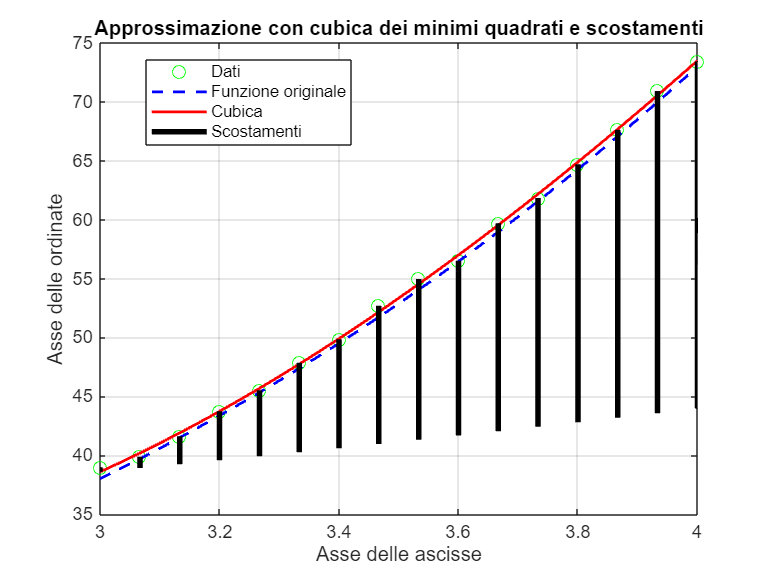

xlabel('Asse delle ascisse')
ylabel('Asse delle ordinate')
hold off
grid on %attiva la griglia

### TASK 3.3

Ripetiamo il punto precedente variando il grado del polinomio nell'intervallo tra 1 e 5. 

c = 1; %estremo sinistro
d = 5; %estremo destro
figure(13)

Dobbiamo trovare un polinomio con grado $n-1$ che interpoli i punti considerati. Quindi, di conseguenza, si deve considerare una quantità di punti per la griglia pari a `grado + 1`.

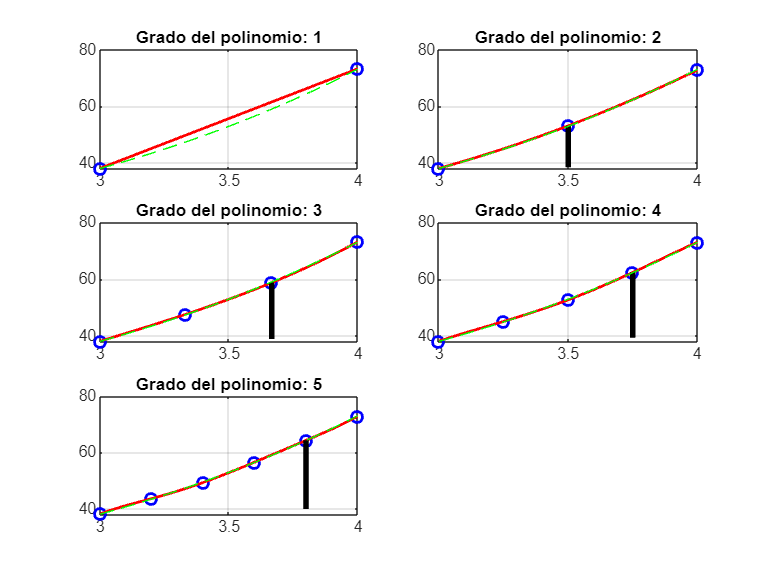

for grado = c:d
    punti = linspace(3, 4, grado + 1); %generazione griglia
    rng(0)
    y_pertubato2 = fun_approx(punti) + 0.1 * randn(1, grado + 1); %calcolo della pertubazione
    p = polyfit(punti, y_pertubato2, grado); % coefficienti ritrovati con polyfit
    y_fit = polyval(p, t_fitta); %polinomio interpolante ottenuto dal comando polyval
    

Il comando `subplot` è utilizzato per creare una griglia di sottofigure all'interno di una singola finestra di figura. Questo permette di visualizzare più grafici fianco a fianco. Ha bisogno di tre parametri in input:

- `m` , in questo caso 3, è il numero di righe nella griglia di sottofigure;

- `n`, in questo caso 2, è il numero di colonne nella griglia di sottofigure;

- `p`, è l'indice della sottofigura corrente (numerato da sinistra a destra e dall'alto verso il basso).

    subplot(3, 2, grado)  


Con questo `plot` si visualizzano sia i punti considerati (con un pallino blu) che il polinomio interpolante (linea rossa).

    plot(punti, y_pertubato2, 'bo', t_fitta, y_fit, 'r', 'linewidth', 1.5)
    hold on


Qui vengono rappresentati gli scostamenti (con una linea continua nera).

    plot([punti(grado),punti(grado)], [y_pertubato2(grado), y_fit(grado)], 'color', 'k', 'LineStyle', '-', 'linewidth', 3);
    title(['Grado del polinomio: ', num2str(grado)]) %num2str(grado) converte il numero relativo al grado in una stringa
    plot(t_fitta, fun_approx(t_fitta), 'g', 'LineStyle', '--') % funzione di partenza data da consegna di colore verde
    hold off
    grid on
end

Questa figura rappresenta, singolarmente, le `subplot` precedenti.

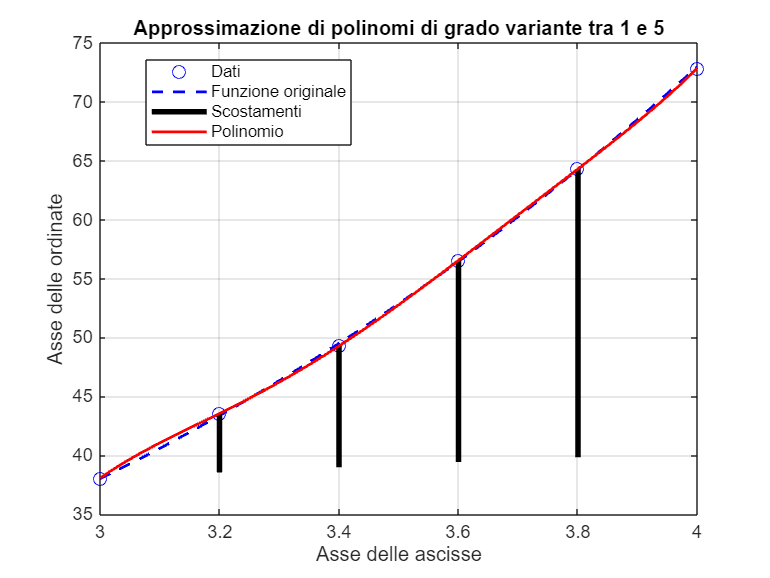

figure(14)

p2 = plot(punti, y_pertubato2, 'bo', 'MarkerSize', 7, 'DisplayName', 'Dati');
hold on
p3 = plot(t_fitta, fun_approx(t_fitta), '--b', 'LineWidth', 1.5, 'DisplayName', 'Funzione originale');
for i = c:d
    p4 = plot([punti(i),punti(i)], [y_pertubato2(i), y_fit(i)], 'color', 'k', 'LineStyle', '-', 'linewidth', 3, 'DisplayName', 'Scostamenti');
end
xlabel('Asse delle ascisse')
ylabel('Asse delle ordinate')
title('Approssimazione di polinomi di grado variante tra 1 e 5')
p5 = plot(t_fitta, y_fit, 'r', 'LineWidth', 1.5, 'DisplayName', 'Polinomio' );
legend([p2, p3, p4(1), p5],  'Location', 'best')
hold off
grid on

ans = 5×1 table
         Residui     
    _________________

     16.9384676803751
    0.681091747397542
    0.608235577306017
    0.749487590870011
    0.687453440507997


### PUNTO 3.4

Si calcolano i residui in norma due delle curve precedentemente ottenute:

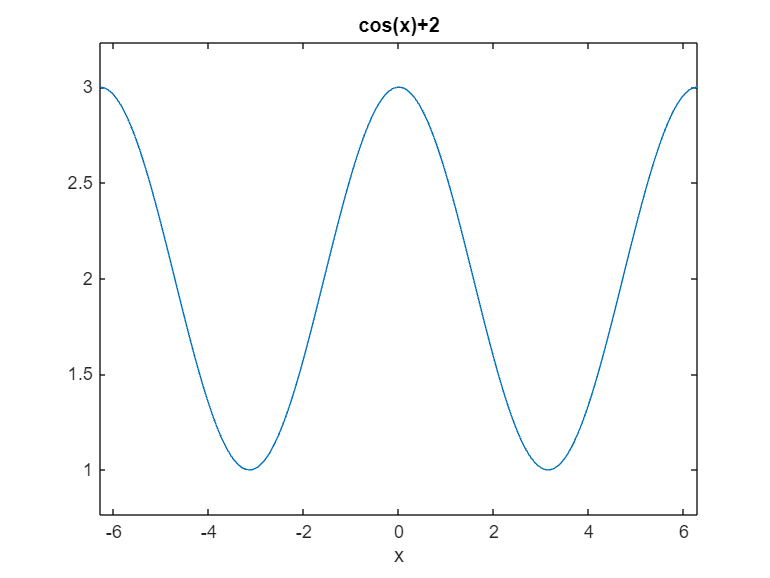

residui = zeros(1, d-c+1);
for grado = c:d
    punti = linspace(3, 4, grado + 1);
    rng(0); %imposta il generatore di numeri casuali a un determinato stato iniziale(seed o seme). In questo caso il seme è impostato a 0.

    y_pertubato2 = fun_approx(punti) + 0.1 * rand(1, grado + 1); 
    p = polyfit(punti, y_pertubato2, grado);
    y_fit = polyval(p, t_fitta);
    residuo = norm(y_fit - fun_approx(t_fitta), 2); %calcolo del residuo in norma due
    residui(grado) = residuo; %il residuo viene attribuito ad un elemento del vettore residui con indice pari a grado
end
table(residui', 'VariableNames', {'Residui'}) %si crea una tabella per la visualizzazione dei residui

Il residuo, calcolato in norma due, risulta diminuire con l'aumentare del grado.

## 4. Quadratura

La quadratura è l'**approssimazione del valore di un integrale definito**:


$$\textrm{If}=\int_a^b f\left(x\right)\textrm{dx}$$


L'approssimazione utilizza una** combinazione lineare dei valori della funzione integranda**:


$$\textrm{Qf}=\sum_{i=1}^n w_i \cdot f\left(x_i \right)$$


- $w_i$ : sono numeri prefissati chiamati **pesi**;

- $x_i$ : sono numeri prefissati chiamati **nodi**.


$$\begin{array}{l}
\textrm{If}\approx \textrm{Qf}\\
\int_a^b f\left(x\right)\textrm{dx}=\sum_{i=1}^n w_i \cdot f\left(x_i \right)\;
\end{array}$$


Le formule di quadratura traggono la loro giustificazione teorica direttamente dalla definizione di integrale definito, secondo la costruzione di **Riemann** (somme di Riemann).

Con le** formule di base**, l'idea è:

- approssimare l'integrale di $f$(area con segno del rettangoloide di $f$) con l'integrale di una funzione $g$ che interpola la $f$ e che sia semplice da integrare:


$$\int_a^b f\left(x\right)\textrm{dx}$$
 
$$\approx$$

$$\int_a^b g\left(x\right)\textrm{dx}$$


Ci sono diversi tipi di formule: 

- **RETTANGOLARE**: dove $g$ interpola il punto $\left(a,f\left(a\right)\right)$:


$$\textrm{Area}\left(R_f \right)\approx \textrm{Area}\left(R_r \right)\;\equiv \left(b-a\right)\cdot f\left(a\right)$$


- **DEL PUNTO MEDIO**: dove $g$ interpola il punto $\left(m,f\left(m\right)\right)$:


$$\begin{array}{l}
\textrm{Area}\left(R_f \right)\approx \textrm{Area}\left(R_{\textrm{pm}} \right)\;\equiv \left(b-a\right)\cdot f\left(m\right)\\
m=\frac{a+b}{2}
\end{array}$$


- **TRAPEZOIDALE**: dove $g$ interpola il punto $\left(a,f\left(a\right)\right),\left(b,f\left(b\right)\right)$:


$$\textrm{Area}\left(R_f \right)\approx \textrm{Area}\left(R_t \right)\;\equiv \left(b-a\right)\cdot \frac{f\left(a\right)+f\left(b\right)}{2}$$


- **DI SIMPSON**: dove $g$ interpola $\left(a,f\left(a\right)\right),\left(m,f\left(m\right)\right),\left(b,f\left(b\right)\right)$:


$$\textrm{Area}\left(R_f \right)\approx \textrm{Area}\left(R_s \right)\;\equiv \frac{b-a}{6}\left(f\left(a\right)+4f\left(m\right)+f\left(b\right)\right)$$


### PUNTO 4.1

Si definisce una funzione composta $f\left(x\right)$ (costituita dalla combinazione delle funzioni elementari).

fun_quadratura = @(x) cos(x) + 2; %definizione funzione
figure(15)

Con `ezplot` visualizziamo l'andamento della funzione, così da trovare un intervallo $\left\lbrack a,b\right\rbrack$ ove la funzione sia positiva e continua.

ezplot(fun_quadratura)

L'intervallo considerato è $\left\lbrack 2,6\right\rbrack$. Con la `figure(15)`, ritroviamo la rappresentazione della funzione in questo intervallo con un titolo contenente il formato "LaTex" della funzione (racchiuso dai delimitatori '`$`'). 

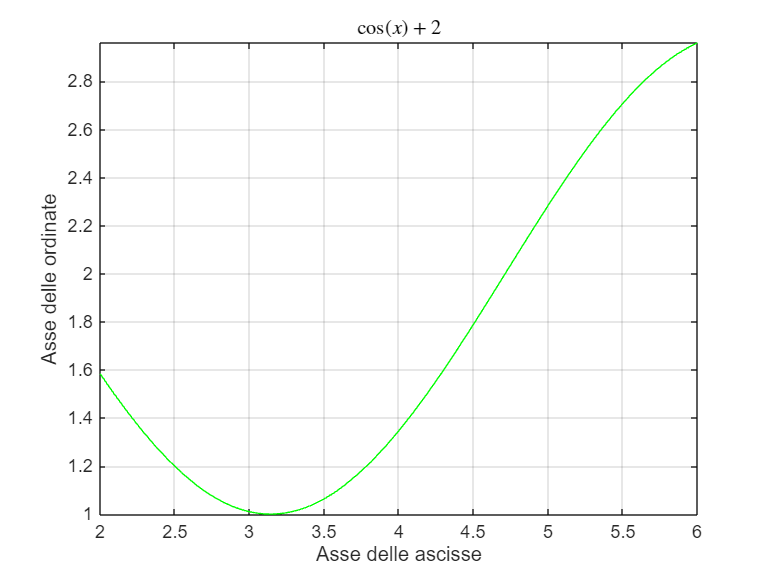

es_sinx = 2; %estremo sinistro

es_desx = 6; %estremo destro
figure(16)
fplot(fun_quadratura, [es_sinx, es_desx], 'g') %funzione nell'intervallo [a, b]
hold on

IF =    6.811287074975393


title('$\cos(x) + 2$', 'Interpreter', 'latex'); %titolo in formato latex
xlabel('Asse delle ascisse')
ylabel('Asse delle ordinate')
hold off
grid on %griglia abilitata

### PUNTO 4.2

Considerando $I=I[f]=\int_a^b f(x)dx$, si calcola l'integrale numerico (definito in un intervallo $\left\lbrack a,b\right\rbrack$ ) con la funzione '`integral`' di Matlab, con `tol = `${10}^{-9}$. 

tol = 1e-9;
IF = integral(fun_quadratura, es_sinx, es_desx, 'AbsTol', tol) %calcolo dell'integrale numerico

### PUNTO 4.3

Si stima l'integrale **I **utilizzando le formule di quadratura composite su $m$ sottointervalli, relative ad una delle seguenti formule base: "Trapezoide" e "Simpson", con $m$ che varia tra le seguenti 5 potenze: *2, 4, 8, 16, 32*. Io ho scelto di utilizzarle entrambe e confrontare le approssimazioni tra loro.

#### Formule composite

L'idea sulla quale si basano:

- suddividere l'intervallo di integrazione in $p$ sottointervalli ($n=p+1$ estremi);

- applicare la formula di base a ogni sottointervallo.


$$\int_a^b f\left(x\right)\textrm{dx}$$
 
$$\approx$$

$$\sum_{j=1}^p \int_{x_j }^{x_{j+1} } f\left(x\right)\textrm{dx}\;\;$$



$$\begin{array}{l}
h=\frac{b-a}{p}\;\;\;\;\;n=p+1\;\;\;x_i =a+h\left(i-1\right)\\
\textrm{Formula}\;\textrm{trapezoidale}\;\textrm{composita}:\\
Q_f f=h\left(\frac{1}{2}f\left(a\right)+\sum_{1=2}^{n-1} f\left(x_i \right)+\frac{1}{2}f\left(b\right)\right)\\
Q_f f=\sum_{i=1}^p h\frac{f\left(x_i \right)+f\left(x_{i+1} \right)}{2}\\
\textrm{Formula}\;\textrm{di}\;\textrm{Simpson}\;\textrm{composita}:\\
\frac{\bar{h} }{3}\left(f\left(x_1 \right)+4\sum_{i\;\textrm{pari}}^{n-1} f\left(x_i \right)+2\sum_{i\;\textrm{dispari}}^{n-1} f\left(x_i \right)+f\left(x_n \right)\right)\\
\bar{h} \;\;\;è\;\textrm{la}\;\textrm{spaziatura}\;\textrm{tra}\;\textrm{due}\;\textrm{nodi}\;\textrm{conesecutivi}\;\left\lbrack \bar{h} =\frac{h}{2}\right\rbrack 
\end{array}$$


m_values = [2, 4, 8, 16, 32]; %le m potenze riportate nella consegna
trapezoide = zeros(size(m_values)); %vettore con i risultati risultanti dall'utilizzo della formula trapezoidale
simpson = zeros(size(m_values)); %vettore con i risultati risultanti dall'utilizzo della formula di Simpson
function int = trapezoidale(f, a, b, m) %funzione che sviluppa la formula trapezoidale
h = (b-a)/(m-1);
breaks = a:h:b;
y = f(breaks);
int = h*(0.5*y(1) + sum(y(2:end-1)) + 0.5*y(end));
end
function int2 = Qf_Simpson(f, a, b, m) %funzione che sviluppa la formula di Simpson
h2 = (b-a)/(m-1);
breaks = a+h2*(0:m-1);
puntimedi = breaks(2:2:end-1);
est_sttintervll = breaks(3:2:end-2);
fpmedi = f(puntimedi);
f_estrstt = f(est_sttintervll);
fa = f(a);
fb = f(b);
int2 = (h2/3)*(fa+4*sum(fpmedi)+2*sum(f_estrstt)+fb);
end
for i = 1:length(m_values) %calcolo dell'approssimazione dell'integrale considerando le m potenze 
    m = m_values(i);
    trapezoide(i) = trapezoidale(fun_quadratura, es_sinx, es_desx, m);
    simpson(i) = Qf_Simpson(fun_quadratura, es_sinx, es_desx, m);
end
Trap = trapezoide';
Simp = simpson';

erroriTr =    2.276759825231055
   0.181554705827211
   0.032523342038925
   0.007052587612249
   0.001649730017721


Si calcola l'errore di discretizzazione relativo alla formula trapezoidale...

erroriTr = abs( Trap - IF)

erroriSimp =    0.752589141504428
   2.981363772193657
   1.560944135545788
   0.766957795324439
   0.377403454901810


e poi quello relativo alla formula di Simpson.

erroriSimp = abs( Simp - IF)

T = 5×5 table
    m(i)     trapezoide(i)         simpson(i)        errori Simpson       errori trapezoide 
    ____    ________________    ________________    _________________    ___________________

      2     9.08804690020645    6.05869793347096    0.752589141504428       2.27675982523106
      4      6.9928417808026    3.82992330278174     2.98136377219366      0.181554705827211
      8     6.84381041701432    5.25034293942961     1.56094413554579     0.0325233420389246
     16     6.81833966258764    6.04432927965095    0.766957795324439    0.00705258761224936
     32     6.81293680499311    6.43388362007358     0.37740345490181     0.0016497300177214


T = table(m_values', Trap, Simp, erroriSimp, erroriTr, 'VariableNames', {'m(i)', 'trapezoide(i)', 'simpson(i)', 'errori Simpson', 'errori trapezoide'}) %tabelle per il confronto dei dati ottenuti

Considerando che l'integrale è pari a :

IF

IF =    6.811287074975393


La formula che risulta avere un risultato più vicino a questo valore è quella trapezoidale, ma con $m=32$. Abbiamo un errore molto vicino allo zero e un'approssimazione quasi esatta. 

### PUNTO 4.4

**Costruzione di formule di quadratura. **Fissare 4 nodi distinti **non** **equispaziati**, $x_i \in [1,5]$  di una formula di quadratura


$$Q[f]=w_1f(x_1)+w_2f(x_2)+w_3f(x_3)+w_4f(x_4)$$
 

num_nodi = 4; %numero di nodi
aQuad = 1; %estremo sinistro
bQuad = 5; %estremo destro
xNodi = aQuad + (bQuad - aQuad)*rand(num_nodi, 1); %generazione casuale di nodi 
xNodi = sort(xNodi); %ordina gli elementi del vettore in ordine crescente
 V = zeros(num_nodi, num_nodi); %Inizializzazione matrice dei polinomi di base
    for i = 1:num_nodi
        V(i, :) = xNodi(i).^(0:3); %calcolo dei valori dei polinomi di base nei nodi
    end
   b_vec = zeros(num_nodi, 1); %vettore dei risultati esatti degli integrali dei polinomi
    for i = 1:num_nodi
        b_vec(i) = (bQuad^i - aQuad^i) / i;
    end
    %calcolo dei pesi come richiesto da consegna
  w = V' \ b_vec;

Questa riga di codice calcola l'integrale approssimato moltiplicando i pesi per i valori della funzione campionata nei nodi e sommandoli.

Quad = sum(w(1:num_nodi) .* fun_quadratura(xNodi(1:num_nodi)))

Quad =    6.683527561694007


È un approssimazione quasi vicina al risultato.

### PUNTO 4.5

Determinare i valori dei pesi $w_i$ affinché la formula risulti esatta per polinomi algebrici di grado al più 3 (costruire e risolvere il sistema $B^Tw=I$).

I pesi sono stati calcolati utilizzando la seguente formula: $w=\frac{B^T }{I}$

table(w, 'VariableNames', {'Pesi'}) %tabella per la visualizzazione dei pesi

ans = 4×1 table
           Pesi       
    __________________

      2.90186613263593
    -0.980900822189683
      37.6288338156221
     -35.5497991260684
